# Compare group membership to mock obs. sample

Find several metrics for comparing the actual group membership based on the halo-finder and the mock observational sample. 

mock sample based on Yang method 

## load relavent things

bp=illustris.set_env(100,'nomount');

*** Mounting simulation files *** 
*** cosmolgy for TNG100 has been set: *** 
hub= 0.677 
Omm = 0.31 
Oml= 0.69 
Omb= 0.0486 
***  *** 
*** You are now analyzing the TNG100 Simulation. ENJOY!  *** 


fprintf('done \n')

done 


global illUnits
loadFofSub;

snap not defined, defaulting to snap=99 


subsInfo=illustris.infrastructure.build_sub_fof_connection(subs,fofs);
snap=99;
massThresh=10^9;
hostThresh=10^11;
sampleMask=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap);
centralMask=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap,'centrals');
satMask=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap,'sats');
% illustris.utils.set_illUnits(snap);load('/home/zinger/workProjects/matlab_scripts/IllustrisTNG/matFiles/newSatSample_sig1_TNG100.mat')
illustris.utils.set_illUnits(snap);
load('/home/zinger/workProjects/matlab_scripts/IllustrisTNG/matFiles/yangSatSample_fiber_sig1_mean_TNG100.mat')
hostMass=fofs.Group_M_Crit200(subsInfo.hostFof+1).*illUnits.massUnit;

cenMask=centralMask & hostMass>=hostThresh;


rv=fofs.Group_R_Crit200.*illUnits.lengthUnit;

galMass= double(subs.SubhaloMassInRadType(illustris.partTypeNum('stars')+1,:).*illUnits.massUnit); % stellar mass within 2*rhalf


## Group finder

centralID=find(cenMask)-1;
hostCentral=subsInfo.hostCentral(satMask);
truNum=zeros(length(centralID),4);
obsNum=zeros(length(centralID),3);
missedSat=zeros(length(centralID),3);
addedSat=zeros(length(centralID),3);
matchedSat=zeros(length(centralID),3);

axx=[2,3;1,3;1,2];
noSat=0;
cnt(1:4)=1;
for i=1:length(centralID)
    r200=fofs.Group_R_Crit200(subsInfo.hostFof(centralID(i)+1)+1);
    satInd=find(subsInfo.hostCentral==centralID(i) & satMask); % indices of satellites for a given group
    
    
    if ~isempty(satInd)
        % count total number of satellites within 2 rvir
        satPos=subs.SubhaloPos(:,satInd);
        satPos=illustris.utils.centerObject(satPos,subs.SubhaloPos(:,centralID(i)+1));
        
        for k=1:4
            if k<4
                projDist=sqrt(sum(satPos(axx(k,:),:).^2,1));
            else
                projDist=sqrt(sum(satPos.^2,1));
            end
            
            msk=projDist<=2.*r200;
            
            truNum(i,k)=sum(msk); %true number of sat's within 2Rvir in projection
            if sum(msk)>0
                inds=cnt(k):cnt(k)+sum(msk)-1;
                
                cnt(k)=inds(end)+1;
                
                truCat(k).satId(inds)=satInd(msk)-1;
                truCat(k).projDist(inds)=projDist(msk)./r200;
                truCat(k).hostId(inds)=subsInfo.hostFof(centralID(i)+1);
            end
        end
        
        
        % find how many missed / added satellites
        
        for k=1:3
            truList=satInd-1; % id's of actual group satelites.
            switch k
                case 1
                    satList=satTabX.satID(satTabX.centralID==centralID(i));
                case 2
                    satList=satTabY.satID(satTabY.centralID==centralID(i));
                case 3
                    satList=satTabZ.satID(satTabZ.centralID==centralID(i));
            end
            
            for j=1:length(satList)
                indx=find(satList(j)==truList);
                
                if ~isempty(indx)
                    satList(j)=-100;
                    truList(indx)=-100;
                end
            end
            
            addedSat(i,k)=sum(satList~=-100);
            missedSat(i,k)=sum(truList~=-100);
            matchedSat(i,k)=sum(satList==-100);
        end
        
        
        
    else
        noSat=noSat+1;
    end
    
    obsNum(i,1)=sum(satTabX.centralID==centralID(i));
    obsNum(i,2)=sum(satTabY.centralID==centralID(i));
    obsNum(i,3)=sum(satTabZ.centralID==centralID(i));
end

fprintf('No of systems with no sats: %i \n',noSat);

No of systems with no sats: 8847 


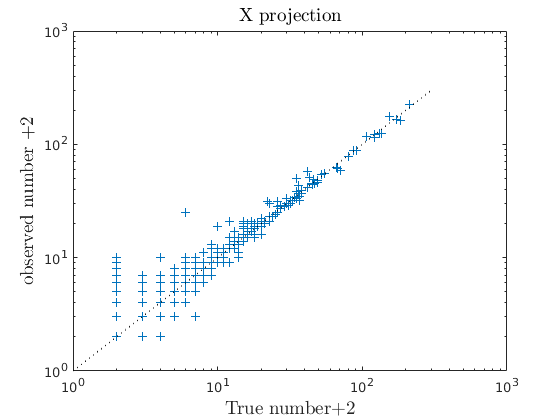

% plot

figure
loglog(truNum(:,1)+2,obsNum(:,1)+2,'+')
hold on
loglog([1 300],[1 300],':k')
xlabelmine('True number+2');
ylabelmine('observed number +2');
titlemine('X projection');

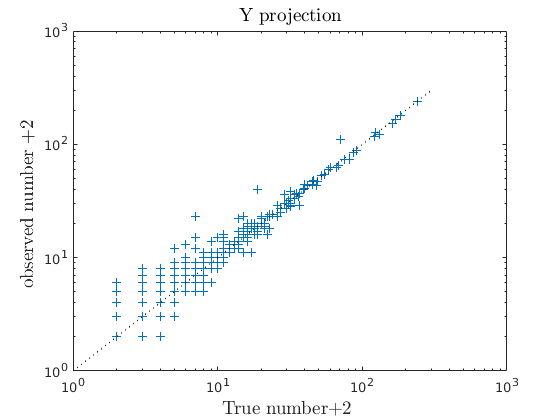



figure
loglog(truNum(:,2)+2,obsNum(:,2)+2,'+')
hold on
loglog([1 300],[1 300],':k')
xlabelmine('True number+2 ');
ylabelmine('observed number +2  ');
titlemine('Y projection');

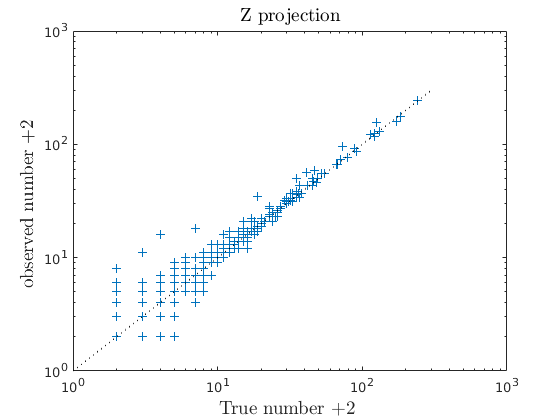



figure
loglog(truNum(:,3)+2,obsNum(:,3)+2,'+')
hold on
loglog([1 300],[1 300],':k')
xlabelmine('True number +2 ');
ylabelmine('observed number +2 ');
titlemine('Z projection');

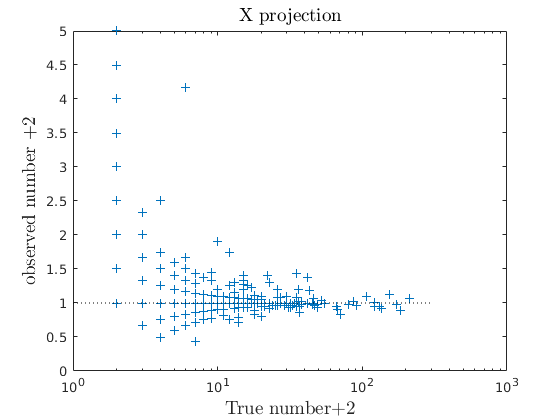



% plot

figure
semilogx(truNum(:,1)+2,(obsNum(:,1)+2)./(truNum(:,1)+2),'+')
hold on
loglog([1 300],[1 1],':k')
xlabelmine('True number+2');
ylabelmine('observed number +2');
titlemine('X projection');

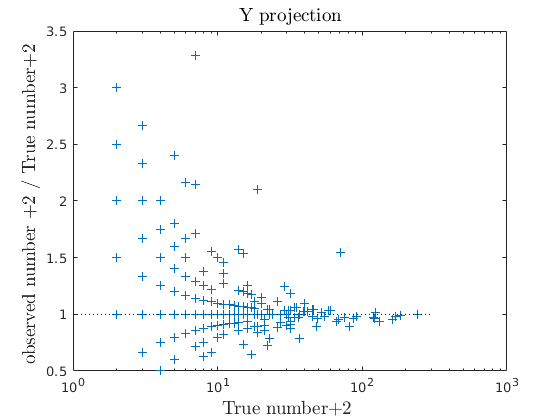



figure
semilogx(truNum(:,2)+2,(obsNum(:,2)+2)./(truNum(:,2)+2),'+')
hold on
loglog([1 300],[1 1],':k')
xlabelmine('True number+2 ');
ylabelmine('observed number +2 / True number+2 ');
titlemine('Y projection');

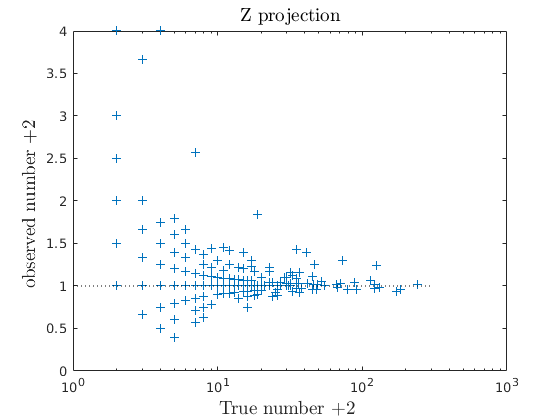



figure
semilogx(truNum(:,3)+2,(obsNum(:,3)+2)./(truNum(:,3)+2),'+')
hold on
semilogx([1 300],[1 1],':k')
xlabelmine('True number +2 ');
ylabelmine('observed number +2 ');
titlemine('Z projection');

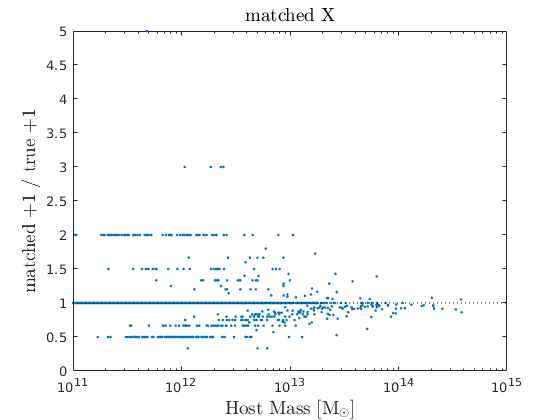

figure
semilogx(hostMass(cenMask),(matchedSat(:,1)+1)./(truNum(:,1)+1),'.')
hold on
semilogx([1e11 1e15],[1 1],':k')
xlabelmine('Host Mass $[\mathrm{M_\odot}]$');
ylabelmine('matched +1 / true +1');
titlemine('matched X');

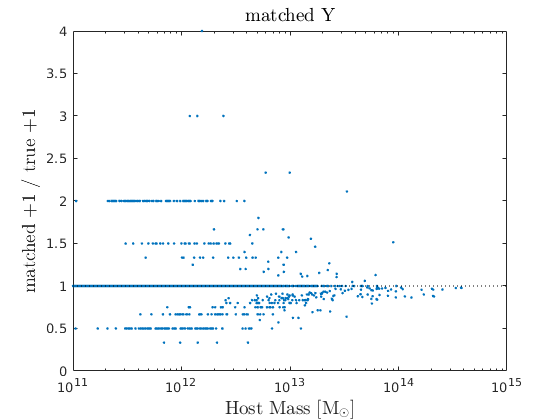


figure
semilogx(hostMass(cenMask),(matchedSat(:,2)+1)./(truNum(:,2)+1),'.')
hold on
semilogx([1e11 1e15],[1 1],':k')
xlabelmine('Host Mass $[\mathrm{M_\odot}]$');
ylabelmine('matched +1 / true +1');
titlemine('matched Y');

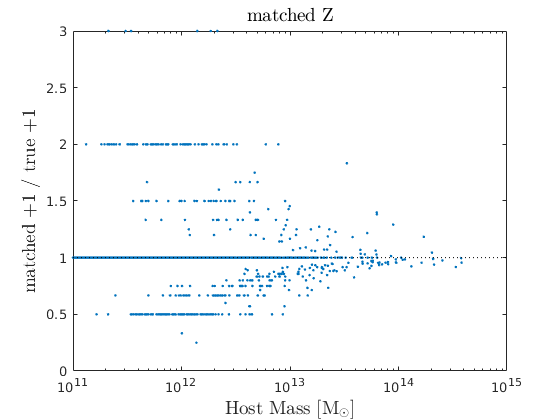


figure
semilogx(hostMass(cenMask),(matchedSat(:,3)+1)./(truNum(:,3)+1),'.')
hold on
semilogx([1e11 1e15],[1 1],':k')
xlabelmine('Host Mass $[\mathrm{M_\odot}]$');
ylabelmine('matched +1 / true +1');
titlemine('matched Z');

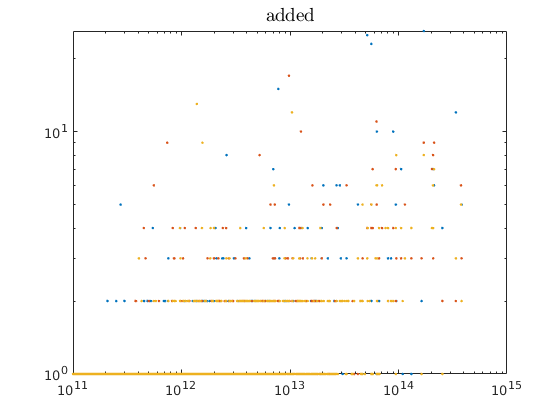


figure
loglog(hostMass(cenMask),addedSat(:,1)+1,'.')
hold on
loglog(hostMass(cenMask),addedSat(:,2)+1,'.')
loglog(hostMass(cenMask),addedSat(:,3)+1,'.')
titlemine('added');

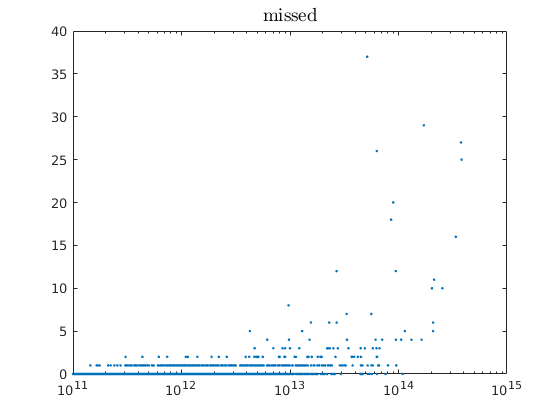


figure
semilogx(hostMass(cenMask),missedSat(:,1),'.')
titlemine('missed');

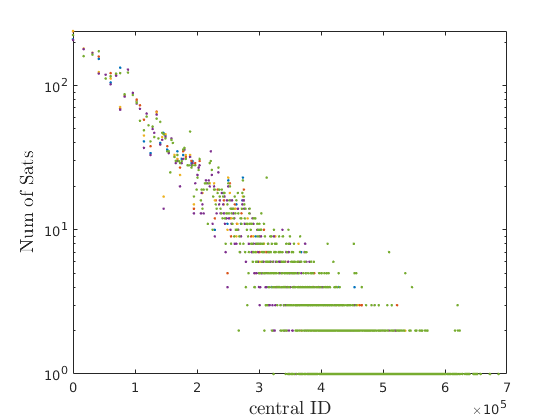


figure

semilogy(centralID,truNum,'.')
hold on
semilogy(centralID,obsNum(:,1),'.')
xlabelmine('central ID');
ylabelmine('Num of Sats');

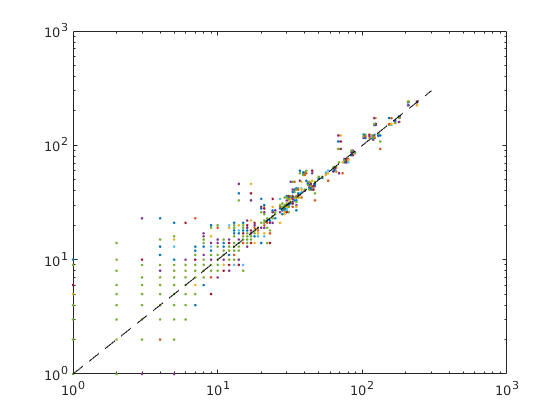


figure

loglog(truNum,obsNum(:,1),'.')

hold on
loglog(truNum,obsNum(:,2),'.')
loglog(truNum,obsNum(:,3),'.')
loglog([1 300],[1 300],'--k')

## plot 2d-histogram for stellar mass - distance form host

X projection 


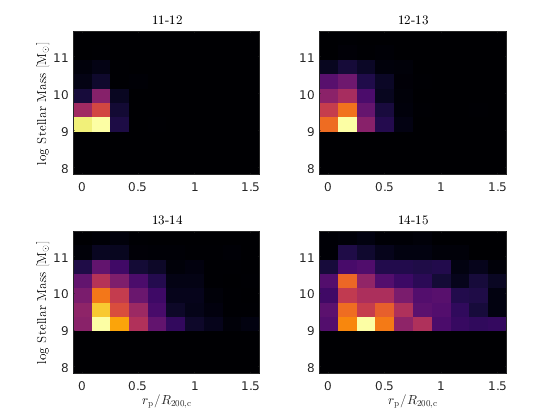

Y projection 


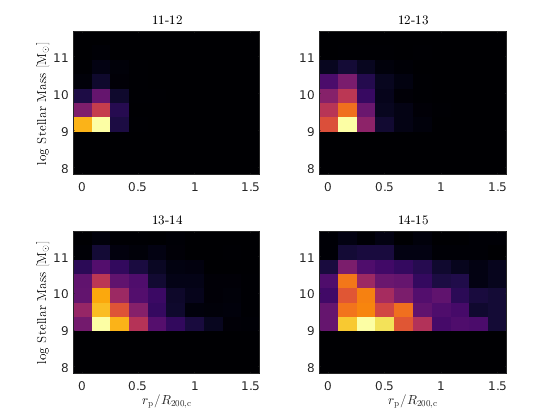

Z projection 


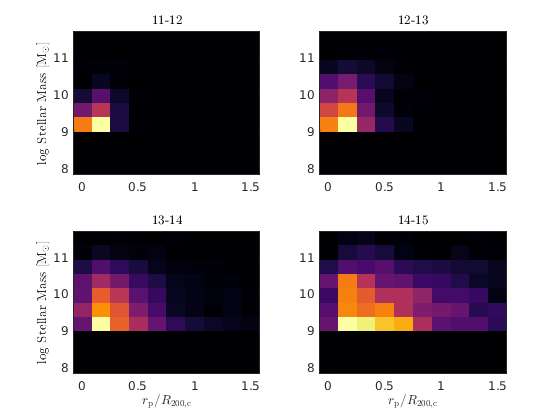

cmap=inferno(256);

for k=1:3
    fprintf('')
    switch k
        case 1
            satTab=satTabX;
            projTag='X';
        case 2
            satTab=satTabY;
            projTag='Y';
        case 3
            satTab=satTabZ;
            projTag='Z';
    end
    fprintf([projTag ' projection \n'])
    
    mhost=fofs.Group_M_Crit200(satTab.hostID+1).*illUnits.massUnit;
    
    mask11=log10(mhost)>=11 & log10(mhost)<12;
    mask12=log10(mhost)>=12 & log10(mhost)<13;
    mask13=log10(mhost)>=13 & log10(mhost)<14;
    mask14=log10(mhost)>=14 & log10(mhost)<15;
    
    %
    gm=log10(galMass(satTab.satID+1));
    rp=satTab.Projected_Distance./rv(satTab.hostID+1);
    
    
    [bird11, binsize, xxlim,yylim]= histogram2d(rp(mask11),gm(mask11),ones(size(gm(mask11))),'len',10,'xlim',[0 1.5],'ylim',[8 11.5]);
    
    [bird12, binsize, xxlim,yylim]= histogram2d(rp(mask12),gm(mask12),ones(size(gm(mask12))),'len',10,'xlim',[0 1.5],'ylim',[8 11.5]);
    
    [bird13, binsize, xxlim,yylim]= histogram2d(rp(mask13),gm(mask13),ones(size(gm(mask13))),'len',10,'xlim',[0 1.5],'ylim',[8 11.5]);
    
    [bird14, binsize, xxlim,yylim]= histogram2d(rp(mask14),gm(mask14),ones(size(gm(mask14))),'len',10,'xlim',[0 1.5],'ylim',[8 11.5]);
    
    %plot
    
    figure
    subplot(2,2,1)
    imagesc(xxlim,yylim,bird11(:,:,1))
    set(gca,'Ydir','normal')
    colormap(cmap)
    ylabelmine('log Stellar Mass $[\mathrm{M_\odot}]$');
    titlemine('11-12');
    
    subplot(2,2,2)
    imagesc(xxlim,yylim,bird12(:,:,1))
    set(gca,'Ydir','normal')
    colormap(cmap)
    titlemine('12-13');
    
    subplot(2,2,3)
    imagesc(xxlim,yylim,bird13(:,:,1))
    set(gca,'Ydir','normal')
    colormap(cmap)
    xlabelmine('$r_\mathrm{p}/R_\mathrm{200,c}$');
    ylabelmine('log Stellar Mass $[\mathrm{M_\odot}]$');
    titlemine('13-14');
    
    subplot(2,2,4)
    imagesc(xxlim,yylim,bird14(:,:,1))
    colormap(cmap)
    set(gca,'Ydir','normal')
    xlabelmine('$r_\mathrm{p}/R_\mathrm{200,c}$');
    titlemine('14-15');
end

## plot 2d-histogram for stellar mass - distance form host - true cat

% cmap=inferno(256);
% 
% for k=1:3
%     switch k
%         case 1
%             satTab=satTabX;
%             projTag='X';
%         case 2
%             satTab=satTabY;
%             projTag='Y';
%         case 3
%             satTab=satTabZ;
%             projTag='Z'
%     end
%     fprintf([projTag ' projection \n'])
%     
%     
%     mhost=fofs.Group_M_Crit200(satTab.hostID+1).*illUnits.massUnit;
%     
%     mask11=log10(mhost)>=11 & log10(mhost)<12;
%     mask12=log10(mhost)>=12 & log10(mhost)<13;
%     mask13=log10(mhost)>=13 & log10(mhost)<14;
%     mask14=log10(mhost)>=14 & log10(mhost)<15;
%     
%     %
%     gm=log10(galMass(satTab.satID+1));
%     rp=satTab.Projected_Distance./rv(satTab.hostID+1);
%     
%     
%     [bird11, binsize, xxlim,yylim]= histogram2d(rp(mask11),gm(mask11),ones(size(gm(mask11))),'len',10,'xlim',[0 1.5],'ylim',[8 11.5]);
%     
%     [bird12, binsize, xxlim,yylim]= histogram2d(rp(mask12),gm(mask12),ones(size(gm(mask12))),'len',10,'xlim',[0 1.5],'ylim',[8 11.5]);
%     
%     [bird13, binsize, xxlim,yylim]= histogram2d(rp(mask13),gm(mask13),ones(size(gm(mask13))),'len',10,'xlim',[0 1.5],'ylim',[8 11.5]);
%     
%     [bird14, binsize, xxlim,yylim]= histogram2d(rp(mask14),gm(mask14),ones(size(gm(mask14))),'len',10,'xlim',[0 1.5],'ylim',[8 11.5]);
%     
%     %plot
%     
%     figure
%     subplot(2,2,1)
%     imagesc(xxlim,yylim,bird11(:,:,1))
%     set(gca,'Ydir','normal')
%     colormap(cmap)
%     ylabelmine('log Stellar Mass $[\mathrm{M_\odot}]$');
%     titlemine('11-12');
%     
%     subplot(2,2,2)
%     imagesc(xxlim,yylim,bird12(:,:,1))
%     set(gca,'Ydir','normal')
%     colormap(cmap)
%     titlemine('12-13');
%     
%     subplot(2,2,3)
%     imagesc(xxlim,yylim,bird13(:,:,1))
%     set(gca,'Ydir','normal')
%     colormap(cmap)
%     xlabelmine('$r_\mathrm{p}/R_\mathrm{200,c}$');
%     ylabelmine('log Stellar Mass $[\mathrm{M_\odot}]$');
%     titlemine('13-14');
%     
%     subplot(2,2,4)
%     imagesc(xxlim,yylim,bird14(:,:,1))
%     colormap(cmap)
%     set(gca,'Ydir','normal')
%     xlabelmine('$r_\mathrm{p}/R_\mathrm{200,c}$');
%     titlemine('14-15');
% end
% 